close("all"); clear; clc;
setmadsympath();

## Geometry

t = sym('t');
N = Frame;
O = Point;

### Rear contact point

Orientation:

yaw = dynamicVariable("psi");
Nyaw = N.orientNew('z',yaw);
pprint(Nyaw.dcm);

$$\left[\begin{array}{ccc} c_{\psi } & -s_{\psi } & 0\\ s_{\psi } & c_{\psi } & 0\\ 0 & 0 & 1 \end{array}\right]$$

Position:

[px,py] = dynamicVariables("p_x","p_y");
Cr = O.locateNew(px.*N.x + py.*N.y);

### Rear wheel

Orientation:

[lean,pitch_r] = dynamicVariables("varphi","theta_r");
Nlean = Nyaw.orientNew('x',lean);
Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta ,r}-s_{\psi }\,s_{\theta ,r}\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta ,r}+c_{\theta ,r}\,s_{\psi }\,s_{\phi }\\ c_{\theta ,r}\,s_{\psi }+c_{\psi }\,s_{\theta ,r}\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta ,r}-c_{\psi }\,c_{\theta ,r}\,s_{\phi }\\ -c_{\phi }\,s_{\theta ,r} & s_{\phi } & c_{\theta ,r}\,c_{\phi } \end{array}\right]$$

Position:

rr = newParameters("r_r");
Or = Cr.locateNew(-rr.*Nlean.z);

### Rear chassis

Orientation:

pitch = dynamicVariable("theta");
Npitch = Nlean.orientNew('y',pitch);
pprint(Npitch.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta }-s_{\psi }\,s_{\theta }\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta }+c_{\theta }\,s_{\psi }\,s_{\phi }\\ c_{\theta }\,s_{\psi }+c_{\psi }\,s_{\theta }\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta }-c_{\psi }\,c_{\theta }\,s_{\phi }\\ -c_{\phi }\,s_{\theta } & s_{\phi } & c_{\theta }\,c_{\phi } \end{array}\right]$$

Position:

[b,h] = newParameters('b','h');
Ob = Cr.locateNew(b.*Npitch.x - h.*Npitch.z);

### Front chassis

Orientation:

caster = newParameters("varepsilon");
Nc = Npitch.orientNew('y',caster);
steer = dynamicVariable("delta");
Nsteer = Nc.orientNew('z',steer);

Position:

[a,e,f] = newParameters('a','e','f');
OB = Cr.locateNew(b.*Npitch.x + a.*Nc.x);
Oh = OB.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front contact

Orientation:

yaw_f = dynamicVariable("psi_f");
Nyaw_f = N.orientNew('z',yaw_f);

Position:

[pxf,pyf] = dynamicVariables("p_xf","p_yf");
Cf =  O.locateNew(pxf.*N.x + pyf.*N.y);

### Front wheel

Orientation:

[lean_f,pitch_f] = dynamicVariables("varphi_f","theta_f");
Nlean_f = Nyaw_f.orientNew('x',lean_f);
Npitch_f = Nlean_f.orientNew('y',pitch_f);

Position:

rf = newParameters("r_f");
Of = Cf.locateNew(-rf.*Nlean_f.z);

## Rigid bodies

### Rear chassis

mb = newParameters('m_r');
[Ibx,Iby,Ibz] = newParameters('I_rx','I_ry','I_rz');
Ibxz = newParameters('C_rxz');
Ib = inertia(Ibx,Iby,Ibz,'Ixz',Ibxz);
rear_chassis = Body(Npitch,Ob,Ib,mb);

### Rear wheel

iry = newParameters('i_ry');
Ir = inertia(0,iry,0);
rear_wheel = Body(Npitch_r,Or,Ir,0);

### Front chassis

mh = newParameters('m_f');
[Ihx,Ihz] = newParameters('I_fx','I_fz');
Ih = inertia(Ihx,0,Ihz);
front_chassis = Body(Nsteer,Oh,Ih,mh);

### Front wheel

ify = newParameters('i_fy');
If = inertia(0,ify,0);
front_wheel = Body(Npitch_f,Of,If,0);

## Generalized coordinates

q_ind = [
    px;
    py;
    yaw;
    lean;
    steer;
    pitch_r;
    pitch_f
    ];

reach = dynamicVariable("beta");

q_dep = [
    pitch;
    reach;
    pxf;
    pyf;
    yaw_f;
    lean_f
    ];

q = GeneralizedCoordinates([q_ind;q_dep],q_dep);
qd = diff(q.All);

## Quasi-velocities

u_names = {
    'v_y';
    'omega_psi';
    'omega_varphi';
    'omega_delta';
    'omega_theta_r'
    };

u_ind = dynamicVariables(u_names{:}).';
u_dep = dynamicVariables('u',6:13);
u = GeneralizedCoordinates([u_ind;u_dep],u_dep);

## Force inputs

Msteer = dynamicVariable("tau_delta");
F = Msteer;

## Constraints

### Holonomic

Locate front contact point relative to front wheel center:

[lx,lz] = newParameters("l_x","l_z");
Of2 = Oh.locateNew(lx.*Nsteer.x + lz.*Nsteer.z);
Nc2 = Nsteer.orientNew('y',-caster);
Nreach = Nc2.orientNew('y',reach);
Cf2 = Of2.locateNew(rf.*Nreach.z);

Front contact constraint:

rOfCf = Cf2.posFrom(Of2,Nc2);
pprint(rOfCf)

$$\left[\begin{array}{c} r_{f}\,s_{\beta }\\ 0\\ c_{\beta }\,r_{f} \end{array}\right]$$

hc_Cf = Cf2.posFrom() - [pxf,pyf,0].';

Reach constraint:

hc_reach = (Nc2.dcm*diff(rOfCf,reach)).'*N.z;

Front yaw:

Rf = Nc2.dcm;
hc_yaw_f = sin(yaw_f)*Rf(2,2) + cos(yaw_f)*Rf(1,2);

Front lean:

hc_lean_f = sin(lean_f) - Rf(3,2);

Collect:

hc = [
    hc_Cf;
    hc_reach;
    hc_yaw_f;
    hc_lean_f
    ];

hc = simplify(expand(hc));

### Nonholonomic

No slip rear:

nhcr = noslip(rear_wheel,Cr.posFrom(Or,Npitch_r));

No slip front:

nhcf = noslip(front_wheel,Cf.posFrom(Of,Npitch_f));

Collect:

nhc = [
    nhcr(1);
    nhcf(1)
    ];

nhc = simplify(expand(nhc));

## Gibbs Appell

X = StateVector(q,u);
C = Constraints(hc,nhc);
GA = GibbsAppell(X,C,F);

## Kinematics

vCr = Twist(Pose(Nyaw,Cr)).TranslationalVelocity;
kdes = u_ind - [
    vCr(2);
    diff([yaw,lean,steer,pitch_r].',t);
    ];

GA.kinematics(kdes);
qdsub = GA.Kinematics.ForcingVector;

## Forces and moments

### Steering torque

Csteer = newParameters("C_delta");
Mz = Msteer - Csteer.*u_ind(4);
front_chassis.applyMoment(Nsteer,Mz.*N.z);
rear_chassis.applyMoment(Nsteer,-Mz.*N.z);

### Rear tire

[Cr1,Cr2] = newParameters("C_r1","C_r2");
vCr = simplify(expand(subs(vCr,qd,qdsub)));
slip_r = -atan(vCr(2)/vCr(1));
Yr = Cr1*slip_r + Cr2*lean;
Zr = newParameters('Z_r');
rear_wheel.applyForce(Nyaw,Cr,Yr*N.y + Zr.*N.z);

### Front tire

[Cf1,Cf2] = newParameters("C_f1","C_f2");
vCf = Twist(Pose(Nyaw_f,Cf)).TranslationalVelocity;
vCf = subs(vCf,qd,qdsub);
slip_f = -atan(vCf(2)/vCf(1));
Yf = Cf1*slip_f + Cf2*lean_f;
Zf = newParameters("Z_f");
front_wheel.applyForce(Nyaw_f,Cf,Yf.*N.y + Zf.*N.z);

### Gravity

bodies = [
    rear_chassis;
    rear_wheel;
    front_chassis;
    front_wheel
    ];

g = newParameters('g');
fg = @(b)b.applyForce(N,b.MassCenter,b.Mass*g.*N.z);
arrayfun(fg,bodies);

## Dynamics

GA.dynamics(bodies);

## Equations of Motion

GA.equations();

## Straight running conditions

q0 = zeros(size(q.All),"sym");
l = newParameters('l');
q0(10) = b + l;
vx = sym('V');
w = -vx/rr;
u0 = [0,0,0,0,w].';
F0 = zeros(size(F),"sym");
GA.trimPoint(q0,u0,[],F0);

## Linearization

GA.linearize();

## State space

X = GA.LinearizedEquations.States;
F = GA.LinearizedEquations.Inputs;
M = GA.LinearizedEquations.MassMatrix;
H = GA.LinearizedEquations.ForcingMatrix;
G = GA.LinearizedEquations.InputMatrix;

### Geometric simplifications

Consider the motorcycle upright and at rest, the caster frame here is:

Ncaster = N.orientNew('y',caster);

Locate front wheel center:

Pa = Point;
l = newParameters('l');
Wf = Pa.locateNew(l.*N.x - rf.*N.z);

Locate front chassis mass center :

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Ncaster.x + f.*Ncaster.z);

Now locate in inertial frame:

[j,k] = newParameters('j','k');
rAGf = simplify(expand(Gf.posFrom(Pa)));
pprint(rAGf)

$$\left[\begin{array}{c} a\,c_{\varepsilon }+c_{\varepsilon }\,e+f\,s_{\varepsilon }\\ 0\\ c_{\varepsilon }\,f-a\,s_{\varepsilon }-e\,s_{\varepsilon } \end{array}\right]$$

Solve for chord length and vertical offset:

sol_af = solve(rAGf([1,3]) - [k;-j],[a,f]);
asub = simplify(expand(sol_af.a));
fsub = simplify(expand(sol_af.f));
pprint(asub);

$$c_{\varepsilon }\,k-e+j\,s_{\varepsilon }$$

pprint(fsub);

$$k\,s_{\varepsilon }-c_{\varepsilon }\,j$$

Distance from $P_{b}$ to wheel center:

rBWf = Wf.posFrom(Pb,Ncaster);
pprint(rBWf)

$$\left[\begin{array}{c} c_{\varepsilon }\,l-a+r_{f}\,s_{\varepsilon }\\ 0\\ l\,s_{\varepsilon }-c_{\varepsilon }\,r_{f} \end{array}\right]$$

Solve for front wheelbase:

an = newParameters("a_n");
lsub = solve(cos(caster) == a/(l + an/cos(caster)),l);
pprint(lsub)

$$\frac{a-a_{n}}{c_{\varepsilon }}$$

lsub = subs(lsub,[a,f],[asub,fsub]);
pprint(lsub)

$$-\frac{a_{n}+e-c_{\varepsilon }\,k-j\,s_{\varepsilon }}{c_{\varepsilon }}$$

Substitute into distance: 

ovars = [l,a,f];
nvars = [lsub,asub,fsub];
rBWf = simplify(expand(subs(rBWf,ovars,nvars)));
pprint(rBWf)

$$\left[\begin{array}{c} r_{f}\,s_{\varepsilon }-a_{n}\\ 0\\ -\frac{a_{n}\,s_{\varepsilon }-j+e\,s_{\varepsilon }+{c_{\varepsilon }}^{2}\,j+{c_{\varepsilon }}^{2}\,r_{f}-c_{\varepsilon }\,k\,s_{\varepsilon }}{c_{\varepsilon }} \end{array}\right]$$

lxsub = rBWf(1);
lzsub = rBWf(3);

Subtitute simplifications into state space:

ovars = [a,f,lx,lz];
nvars = [asub,fsub,lxsub,lzsub];
fsimp = @(eq)simplify(expand(subs(eq,ovars,nvars)));
hvar = a - cos(caster)*k + e;
hsimp = @(eq)subs(fsimp(eq),j*sin(caster),hvar);
M = fsimp(M);
H = simplify(expand(hsimp(H)));
G = fsimp(G);

### Independent states

fP = @(x)has(X,x);
Xr = [lean,steer,u.Independent(1:end-1).'];
P = cell2mat(arrayfun(fP,Xr,"uniform",0));

Xind = X(~has(X,[pitch,reach,pxf,pyf,yaw_f,lean_f].'));
eq = P.'*(M*diff(X) - (H*Xind + G*F));
[Mr,fr] = massMatrixForm(eq,Xr);
Mr = simplify(expand(Mr));

pprint(Mr);

$$\left[\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & m_{f}+m_{r} & b\,m_{f}+b\,m_{r}+k\,m_{f} & h\,m_{r}+j\,m_{f} & e\,m_{f}\\ 0 & 0 & b\,m_{f}+b\,m_{r}+k\,m_{f} & I_{\mathrm{fz}}+I_{\mathrm{rz}}+I_{\mathrm{fx}}\,{s_{\varepsilon }}^{2}-I_{\mathrm{fz}}\,{s_{\varepsilon }}^{2}+b^{2}\,m_{f}+b^{2}\,m_{r}+k^{2}\,m_{f}+2\,b\,k\,m_{f} & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+b\,h\,m_{r}+b\,j\,m_{f}+j\,k\,m_{f} & I_{\mathrm{fz}}\,c_{\varepsilon }+b\,e\,m_{f}+e\,k\,m_{f}\\ 0 & 0 & h\,m_{r}+j\,m_{f} & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+b\,h\,m_{r}+b\,j\,m_{f}+j\,k\,m_{f} & I_{\mathrm{fx}}+I_{\mathrm{rx}}-I_{\mathrm{fx}}\,{s_{\varepsilon }}^{2}+I_{\mathrm{fz}}\,{s_{\varepsilon }}^{2}+h^{2}\,m_{r}+j^{2}\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f}\\ 0 & 0 & e\,m_{f} & I_{\mathrm{fz}}\,c_{\varepsilon }+b\,e\,m_{f}+e\,k\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f} & m_{f}\,e^{2}+I_{\mathrm{fz}} \end{array}\right]$$


Hr = simplify(expand(jacobian(fr,Xr)));
Gr = simplify(expand(jacobian(fr,F)));

pprint(Hr);

pprint(Gr);

$$\left[\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 1 \end{array}\right]$$

### MATLAB functions

p = symvar([Mr,Hr,Gr]).';
p(has(p,vx)) = [];
p = [p(1:10);Zf;p(11:end - 1);sym("sigma");p(end)];
M_name = "prydeMotorcycleLinearizedMassMatrix";
H_name = "prydeMotorcycleLinearizedForcingMatrix";
G_name = "prydeMotorcycleLinearizedInputMatrix";
fM = matlabFunction(Mr,"File",M_name,"Vars",{vx,p});
fH = matlabFunction(Hr,"File",H_name,"Vars",{vx,p});
fG = matlabFunction(Gr,"File",G_name,"Vars",{vx,p});

### Numerical test

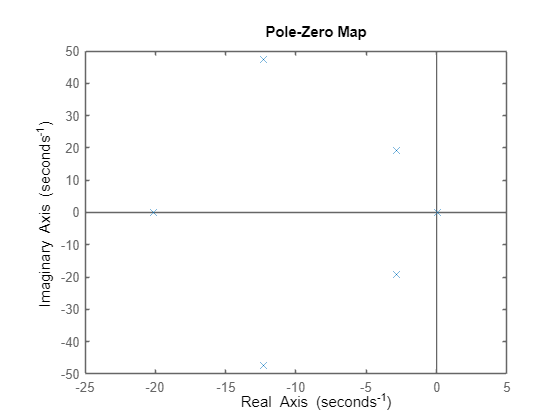

vx0 = 110/3.6;
params = sharpMotorcycle1971Parameters().list();
M0 = fM(vx0,params);
H0 = fH(vx0,params);
G0 = fG(vx0,params);
A0 = M0\H0;
B0 = M0\G0;
sys = ss(A0,B0,eye(size(A0)),0);
pzmap(sys)